clc;
close all;
clear all;

%--- time and space discritization-------

dt = 0.1;                     % Time step
n = 18;                      % number of nodes 

%--- Soil column dimensions--------------

L = 10;                  % length of column (cm)
d = 5.08;                 % diameter of column (cm)
a = (22./7).*(d.^2)./4;  % area of the column
vol = a.*L;              % volume of column
dx = L./(n-1);             % space step

%--- soil, physcial and flow properties-----------------

d50 = 0.0025;     % mean diameter of porous media particles (cm)
theeta = 0.475;   % soil porosity (cm3/cm3)
rho = 1.39;     % soil medium bulk density (g/cc)

Q = 1;      % (ml/min)
V = Q./(theeta.*a) % pore velocity (cm/min)

V = 0.1038

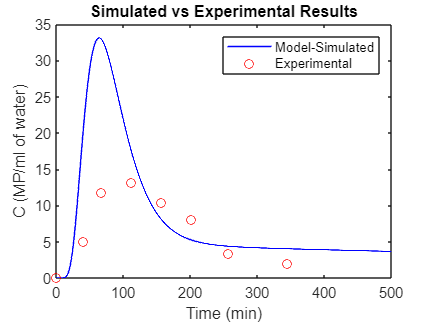

Vv = vol.*theeta;        % Volume of voids (cm3)
Ci = 10667./(dx.*a.*theeta);    % concentration of colloids (particle/ml)

%--- matrix creation----------------

t = (0:dt:500);               % number of time steps
t_sim = t';
PV = Q.*t./Vv;
PV_sim = PV';
x = 0:dx:L;

CC = zeros(length(t),n);
C_star = zeros(length(t),n);
S = zeros(length(t),n);
CCC_star = zeros(length(t),n);
SSS_star = zeros(length(t),n);

% %--- calibrating parameters--------------

lamda = 1.6535; % longitudnal/hydrodynamic dispersivity (cm)
D = lamda.*V; % Diffusion coefficient (cm2/min)
Ka = 0.012034;  % attachment coefficient (per minute)
Kd = 0.002;  % detachment coefficient (per minute)
Kst = 0.02454; % straining coefficient (per minute)
parametric_beta = 0.68; % fitting parameter (-)
S_max = 1500; % max solute retention calculated by calibration
alpha = V.*dx./(2.*D);
beta = (dx.^2)./(D.*dt); % (1/beta) = Courant number (<1)

ls(1,1) = 0;                    % lower sub diagonal
us(1,1) = 1-alpha; us(n,1) = 0;       % uper sub diagonal
d(1,1) = ((1+alpha).*(1-(2.*alpha)))-(2+beta);      % main diagonal (Cauchy BC)
b(1,1) = Ci; b(n,1) = 0;     % boundary conditions
 
ls(2:n-1,1) =  (1+alpha);
us(2:n-1,1) =  (1-alpha);
d(2:n-1,1) = -(2+beta);
b(2:n-1,1) = 0;  % initial condition
% left hand side boundary condition
ls(n,1) = (2.*alpha) ;
d(n,1) = -((2.*alpha)+beta);


%   creating coefficient matrix
A = zeros(n);
for j = 1:n
    A(j,j) = d(j,1);
end
for j=1:n-1
    A(j,j+1) = us(j,1);
end
for j= 2:n
    A(j,j-1) = ls(j,1);
end

% BTC by implicit scheme for all time sereis 
C = zeros(length(t),n);
C(1,:) = b;
for i = 2:length(t)
         b = -beta.*C(i-1,:).';
       
        C(i,:) = A\b;
     C(i-1,:) = C(i,:);

    % %------Retardation (ODE) equation Solver by Runge-Kutta 4th order (RK4) scheme-----------

    for j = 1:n

    %--- defining the equation for slope-----------
      z(1) = 0;
    z(j+1) = z(j) + dx; % down gradient depth from inlet
    si_st = (d50./(d50+z(j))).^parametric_beta;  % depth dependent power law function for straining
    si_at = (1-(S(j)./S_max));

        dS_dt= @(t,C,S) (1./rho).*(theeta.*Ka.*(si_at).*C - Kd.*rho.*S + (theeta.*Kst.*(si_st).*C));
        dC_dt= @(t,C,S) (rho./theeta).*(1./rho).*((theeta.*Ka.*(si_at).*C - Kd.*rho.*S + (theeta.*Kst.*(si_st).*C)));
    %--- solving for average slope (using four slopes) to find concentration value at nest time step-----  

        KS1 = dS_dt(t(j),C(i-1,j),S(i,j));
        KC1 = dC_dt(t(j),C(i-1,j),S(i,j));
        SS_star = S(i-1,j) + KS1.*(dt/2);
        CC_star = C(i-1,j) - KC1.*(dt/2);

        KS2 = dS_dt(t(j)+(dt./2),CC_star,SS_star);
        KC2 = dC_dt(t(j)+(dt./2),CC_star,SS_star);
        SS_doublestar = S(i-1,j) + KS2.*(dt/2);
        CC_doublestar = C(i-1,j) - KC2.*(dt/2);

        KS3 = dS_dt(t(j)+(dt./2),CC_doublestar,SS_doublestar);
        KC3 = dC_dt(t(j)+(dt./2),CC_doublestar,SS_doublestar);
        SS_triplestar = S(i-1,j) + KS3.*(dt);
        CC_triplestar = C(i-1,j) - KC3.*(dt);

        KS4 = dS_dt(t(j)+(dt),CC_triplestar,SS_triplestar);
        KC4 = dC_dt(t(j)+(dt),CC_triplestar,SS_triplestar);

        KS_avg = (KS1+2.*KS2+2.*KS3+KS4)./6;
        KC_avg = (KC1+2.*KC2+2.*KC3+KC4)./6;
        SSS_star(i,j) = S(i-1,j) + KS_avg.*(dt);
        CCC_star(i,j) = C(i-1,j) - KC_avg.*(dt);
        S(i,j) = SSS_star(i,j);
        C(i,j) = CCC_star(i,j);

    end

end
S_sim = S';
%--- plotting graphs-----------------
%--- Experimental results ---

  t_exp = [0; 40.5; 67.5; 112.5; 157.5; 202.5; 257.5; 345];
    C_exp = [0; 5; 11.8; 13.2; 10.4; 8; 3.4; 1.93];

%--- Plotting both model and experimental results ---
figure;

% Plotting model-simulated results
% subplot(2, 1, 1);
plot(t, C(:, (L/dx)+1), 'b-', 'LineWidth', 1);
hold on;

% Plotting experimental results
scatter(t_exp, C_exp, 'ro');
legend('Model-Simulated', 'Experimental');
xlabel('Time (min)'), ylabel('C (MP/ml of water)');
title('Simulated vs Experimental Results');
hold off;

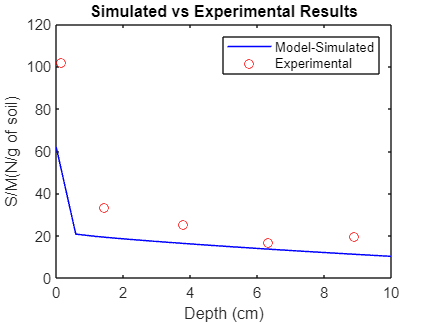



%--- Experimental results ---

    

   x_exp = [0.16; 1.43; 3.81; 6.35; 8.89]; % Adjust as needed
    S_exp = [101.99; 33.38; 25.3; 16.54; 19.43]; % Define your experimental retention profile here

%--- Plotting both model and experimental results ---
figure;

% Plotting model-simulated results
% subplot(2, 1, 1);
plot(x, S((268./dt)+1,:), 'b-', 'LineWidth', 1);
hold on;

% Plotting experimental results
scatter(x_exp, S_exp, 'ro');
legend('Model-Simulated', 'Experimental');
xlabel('Depth (cm)'), ylabel('S/M(N/g of soil)');
title('Simulated vs Experimental Results');